## Simple LiveScript Example

Here's a LiveScript file that gives the user the option to view a sinusoid plus Gaussian white noise in both the time and frequency (Fourier) domain.

The user will have the ability to toggle between both the time and frequency domain plot views as well as change the frequency and amplitude of the sinusoid using embedded uicomponents.

## Parameters

fs = 1000;                      % sampling frequency (Hz)
dur = 1;     % duration (seconds)
f0 = 100; % frequency (Hz)
amp = 0.4; % sinusoid amplitude
plotType = "Time Domain";


## Define time and frequency domain vectors

t = (0:1/fs:dur)'; % time axis vector (seconds)
f = fs*(0:numel(t)-1)/numel(t); % frequency axis vector (Hz)

signal = amp*cos(2*pi*f0*t);
noise = randn(size(t));

xt = signal+noise;
Xw = 20*log10(abs(fft(xt,numel(f))));


## Plot

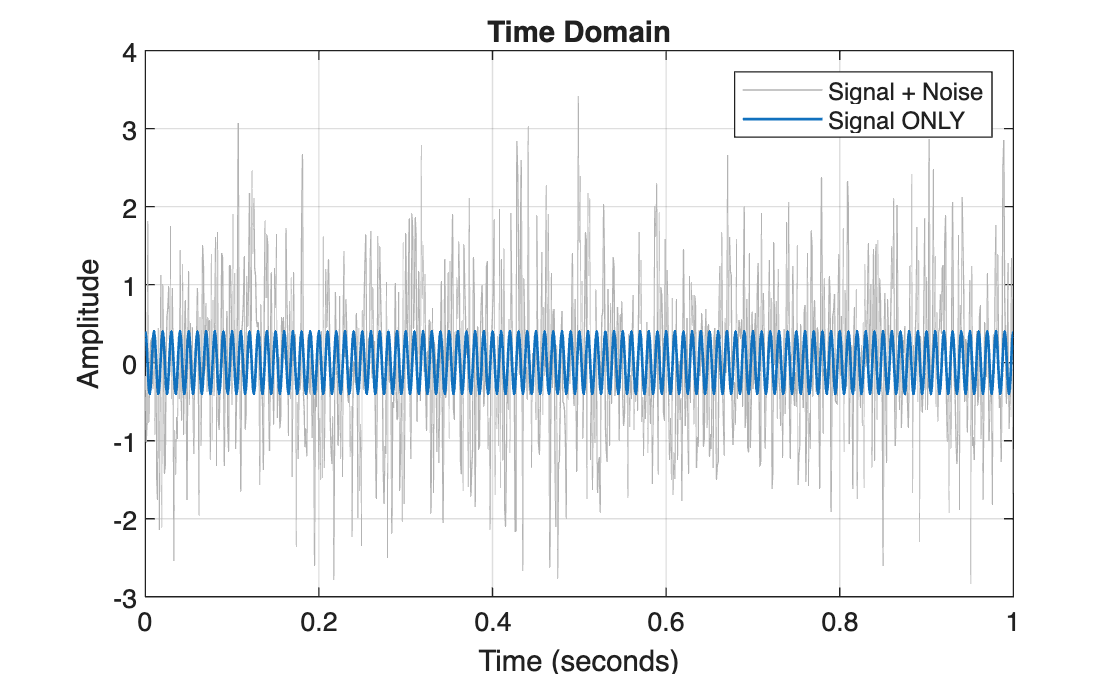

f1 = figure;
ax1 = axes;
cm = colororder;

if plotType == "Time Domain"
    plot(ax1,t,xt,'Color',[0.7, 0.7, 0.7]);
    hold on;
    plot(ax1,t,signal,'Color',cm(1,:),'LineWidth',1);
    
    title('Time Domain');
    xlabel('Time (seconds)');
    ylabel('Amplitude');
    grid on;

    legend({"Signal + Noise", "Signal ONLY"});

elseif plotType == "Frequency Domain"
    plot(ax1,f,Xw,'Color',[0.6, 0.6, 0.6]);
    hold on;
    stem(ax1,f,20*log10(abs(fft(signal,numel(signal)))),'.-','Color',cm(2,:),'LineWidth',1);
    xlim([0 fs/2]);
    ylim([0 60]);

    title('Frequency (Fourier) Domain');
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    grid on;

    legend({"Signal + Noise", "Signal Only"});
end